clear
clc

A = 1:25;
A = reshape(A,[5 5])';
det(A)

ans = 0

trace(A)

ans = 65

rank(A)

ans = 2

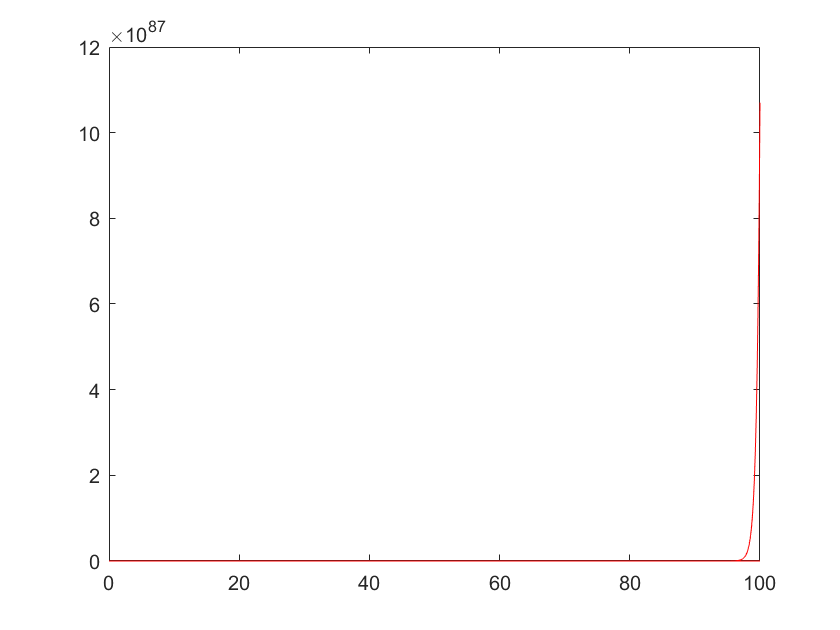

clear
clc

t = [0,100];
y = [10 10];
[t,y] = ode45(@sys0001,t,y);
plot(t,y,'r-')


[r,p,k]=residue([2 5 3 6],[1 6 11 6])

r =    -6.0000
   -4.0000
    3.0000


p =    -3.0000
   -2.0000
   -1.0000


k = 2

[num,den]=residue(r,p,k)

num =     2.0000    5.0000    3.0000    6.0000


den =     1.0000    6.0000   11.0000    6.0000



[z p k]= tf2zp(num,den)

z =   -2.3965 + 0.0000i
  -0.0518 + 1.1177i
  -0.0518 - 1.1177i


p =    -3.0000
   -2.0000
   -1.0000


k = 2

clear
clc

help tf2zpk

tf2zpk - Convert transfer function filter parameters to zero-pole-gain form

    This MATLAB function finds the matrix of zeros z, the vector of poles p, and the
    associated vector of gains k from the transfer function parameters b and a.

    [z,p,k] = tf2zpk(b,a)

    另请参阅 <a href="https://localhost:31515/static/help/signal/ref/sos2zp.html">sos2zp</a>, <a href="https://localhost:31515/static/help/signal/ref/ss2zp.html">ss2zp</a>, <a href="https://localhost:31515/static/help/signal/ref/tf2sos.html">tf2sos</a>, <a href="https://localhost:31515/static/help/signal/ref/tf2ss.html">tf2ss</a>, <a href="https://localhost:31515/static/help/signal/ref/tf2zp.html">tf2zp</a>, <a href="https://localhost:31515/static/help/signal/ref/zp2tf.html">zp2tf</a>

    tf2zpk 的文档



help tf2zp

tf2zp - Convert transfer function filter parameters to zero-pole-gain form

    This MATLAB function finds the matrix of zeros z, the vector of poles p, and the
    associated vector of gains k from the transfer function parameters b and a.

    [z,p,k] = tf2zp(b,a)

    另请参阅 <a href="https://localhost:31515/static/help/signal/ref/sos2zp.html">sos2zp</a>, <a href="https://localhost:31515/static/help/signal/ref/ss2zp.html">ss2zp</a>, <a href="https://localhost:31515/static/help/signal/ref/tf2sos.html">tf2sos</a>, <a href="https://localhost:31515/static/help/signal/ref/tf2ss.html">tf2ss</a>, <a href="https://localhost:31515/static/help/signal/ref/tf2zpk.html">tf2zpk</a>, <a href="https://localhost:31515/static/help/signal/ref/zp2tf.html">zp2tf</a>

    tf2zp 的文档



help zpk2tf

--- 未找到 zpk2tf。改为显示 zp2tf 的帮助。---

zp2tf - Convert zero-pole-gain filter parameters to transfer function form

    This MATLAB function converts a factored transfer function representation...

    [b,a] = zp2tf(z,p,k)

    另请参阅 <a href="https://localhost:31515/static/help/signal/ref/sos2tf.html">sos2tf</a>, <a href="https://localhost:31515/static/help/matlab/ref/ss2tf.html">ss2tf</a>, <a href="https://localhost:31515/static/help/signal/ref/tf2zp.html">tf2zp</a>, <a href="https://localhost:31515/static/help/signal/ref/tf2zpk.html">tf2zpk</a>, <a href="https://localhost:31515/static/help/signal/ref/zp2sos.html">zp2sos</a>, <a href="https://localhost:31515/static/help/signal/ref/zp2ss.html">zp2ss</a>

    zp2tf 的文档



help zp2tf

zp2tf - Convert zero-pole-gain filter parameters to transfer function form

    This MATLAB function converts a factored transfer function representation...

    [b,a] = zp2tf(z,p,k)

    另请参阅 <a href="https://localhost:31515/static/help/signal/ref/sos2tf.html">sos2tf</a>, <a href="https://localhost:31515/static/help/matlab/ref/ss2tf.html">ss2tf</a>, <a href="https://localhost:31515/static/help/signal/ref/tf2zp.html">tf2zp</a>, <a href="https://localhost:31515/static/help/signal/ref/tf2zpk.html">tf2zpk</a>, <a href="https://localhost:31515/static/help/signal/ref/zp2sos.html">zp2sos</a>, <a href="https://localhost:31515/static/help/signal/ref/zp2ss.html">zp2ss</a>

    zp2tf 的文档




type tf2zp tf2zpk 

function [z,p,k] = tf2zp(num,den)
%TF2ZP  Transfer function to zero-pole conversion.
%   [Z,P,K] = TF2ZP(NUM,DEN)  finds the zeros, poles, and gains:
%
%                 (s-z1)(s-z2)...(s-zn)
%       H(s) =  K ---------------------
%                 (s-p1)(s-p2)...(s-pn)
%
%   from a SIMO transfer function in polynomial form:
%
%               NUM(s)
%       H(s) = -------- 
%               DEN(s)
%
%   Vector DEN specifies the coefficients of the denominator in 
%   descending powers of s.  Matrix NUM indicates the numerator 
%   coefficients with as many rows as there are outputs.  The zero
%   locations are returned in the columns of matrix Z, with as many 
%   columns as there are rows in NUM.  The pole locations are returned
%   in column vector P, and the gains for each numerator transfer 
%   function in vector K. 
%
%   For discrete-time transfer functions, it is highly recommended to
%   make the length of the numerator and denominator equal to ensure 
%   correct results.  Yo

type zp2tf 

function [num,den] = zp2tf(z,p,k)
%ZP2TF  Zero-pole to transfer function conversion.
%   [NUM,DEN] = ZP2TF(Z,P,K)  forms the transfer function:
%
%                   NUM(s)
%           H(s) = -------- 
%                   DEN(s)
%
%   given a set of zero locations in vector Z, a set of pole locations
%   in vector P, and a gain in scalar K.  Vectors NUM and DEN are 
%   returned with numerator and denominator coefficients in descending
%   powers of s.  
%
%   See also TF2ZP.

%   J.N. Little 7-17-85
%   Revised 6-27-88
%   Copyright 1984-2008 The MathWorks, Inc.

%   Note: the following will not work if p or z have elements not
%   in complex pairs.

den = real(poly(p(:)));
[~,nd] = size(den);
k = k(:);
[mk,~] = size(k);
if isempty(z), num = [zeros(mk,nd-1),k]; return; end
[m,n] = size(z);
if mk ~= n
    if m == 1
       ctrlMsgUtils.error('Controllib:general:ZNotColumn')
    end
    ctrlMsgUtils.error('Controllib:general:KMismatchZ')
end
for j=1:n
    zj = z(:,j);
    pj = real(poly(

clear
clc

[num,den]=zp2tf([],[-1+2*i -1-2*i],[10])

num =      0     0    10


den =      1     2     5


printsys(num,den)

 
num/den = 
 
         10
   -------------
   s^2 + 2 s + 5


[A B C D] = tf2ss(num,den)

A =     -2    -5
     1     0


B =      1
     0


C =      0    10


D = 0

[a b]=ss2tf(A,B,C,D,1)

a =      0     0    10


b =      1     2     5


clear
clc

A = [0 1; -25 -4];
B = [1 1; 0 1];
C = eye(2);
D = zeros(2,2);

[num1 den1] = ss2tf(A,B,C,D,1)

num1 =      0     1     4
     0     0   -25


den1 =     1.0000    4.0000   25.0000


[num2 den2] = ss2tf(A,B,C,D,2)

num2 =          0    1.0000    5.0000
         0    1.0000  -25.0000


den2 =     1.0000    4.0000   25.0000



printsys(num1,den1)

 
num(1)/den = 
 
        s + 4
   --------------
   s^2 + 4 s + 25
 
num(2)/den = 
 
         -25
   --------------
   s^2 + 4 s + 25


printsys(num2,den2)

 
num(1)/den = 
 
        s + 5
   --------------
   s^2 + 4 s + 25
 
num(2)/den = 
 
       s - 25
   --------------
   s^2 + 4 s + 25


clear
clc

A = [];
B = [];
Aeq = [];
Beq = [];
xm = [-10 -10];
xM = [10 10];
x0 = [5 5];
[x,f key c] = fmincon(@minfun,x0,A,B,Aeq,Beq,xm,xM,@cfun);

c =    10.0000
   16.5000
  -35.0000


c =    10.0000
   16.5000
  -35.0000


c =    10.0000
   16.5000
  -35.0000


c =     4.4721
  -57.8635
   44.8914


c =     4.4721
  -57.8635
   44.8914


c =     4.4721
  -57.8635
   44.8914


c =     4.4722
  -57.8618
   44.8895


c =     4.4722
  -57.8618
   44.8895


c =     4.4722
  -57.8618
   44.8895


c =     4.4523
  -57.5523
   44.6000


c =     4.4623
  -57.7069
   44.7447


c =     4.4623
  -57.7069
   44.7447


c =     4.4623
  -57.7069
   44.7447


c =     4.3773
  -55.8342
   42.9569


c =     4.3773
  -55.8342
   42.9569


c =     4.3773
  -55.8342
   42.9569


c =    -0.8460
  -13.5987
    5.9447


c =    -0.8460
  -13.5987
    5.9447


c =    -0.8460
  -13.5987
    5.9447


c =    -1.8274
   -6.7524
    0.0798


c =    -1.8274
   -6.7524
    0.0798


c =    -1.8274
   -6.7524
    0.0798


c =    -1.9249
   -6.2092
   -0.3658


c =    -1.9249
   -6.2092
   -0.3658


c =    -1.9249
   -6.2092
   -0.3658


c =    -2.3701
   -3.8386
   -2.2913


c =    -2.3701
   -3.8386
   -2.2913


c =    -2.3701
   -3.8386
   -2.2913


c =    -2.3879
   -3.9825
   -2.1296


c =    -2.3879
   -3.9825
   -2.1296


c =    -2.3879
   -3.9825
   -2.1296


c =    -2.6621
   -3.7408
   -2.0971


c =    -2.6621
   -3.7408
   -2.0971


c =    -2.6621
   -3.7408
   -2.0971


c =    -3.8293
   -2.4089
   -2.2618


c =    -3.8071
   -2.5071
   -2.1859


c =    -3.8071
   -2.5071
   -2.1859


c =    -3.8071
   -2.5071
   -2.1859


c =    -6.0300
   -0.1494
   -2.3207


c =    -5.8729
   -0.6988
   -1.9282


c =    -5.8729
   -0.6988
   -1.9282


c =    -5.8729
   -0.6988
   -1.9282


c =    -6.5294
   -0.6861
   -1.2845


c =    -6.5294
   -0.6861
   -1.2845


c =    -6.5294
   -0.6861
   -1.2845


c =    -7.0818
   -0.7297
   -0.6885


c =    -7.0818
   -0.7297
   -0.6885


c =    -7.0818
   -0.7297
   -0.6885


c =    -7.8122
   -0.3227
   -0.3652


c =    -7.8122
   -0.3227
   -0.3652


c = 3×1
   -7.8122
   -0.3227
   -0.3652


c = 3×1
   -8.3321
   -0.0670
   -0.1008


c = 3×1
   -8.3321
   -0.0670
   -0.1008


c = 3×1
   -8.3321
   -0.0670
   -0.1008


c = 3×1
   -8.4953
   -0.0031
   -0.0016


c = 3×1
   -8.4953
   -0.0031
   -0.0016


c = 3×1
   -8.4953
   -0.0031
   -0.0016


c = 3×1
   -8.4752
   -0.0129
   -0.0119


c = 3×1
   -8.4752
   -0.0129
   -0.0119


c = 3×1
   -8.4752
   -0.0129
   -0.0119


c = 3×1
   -8.4954
   -0.0024
   -0.0022


c = 3×1
   -8.4954
   -0.0024
   -0.0022


c = 3×1
   -8.4954
   -0.0024
   -0.0022


c = 3×1
   -8.5000
   -0.0000
   -0.0000


c = 3×1
   -8.5000
   -0.0000
   -0.0000


c = 3×1
   -8.5000
   -0.0000
   -0.0000



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


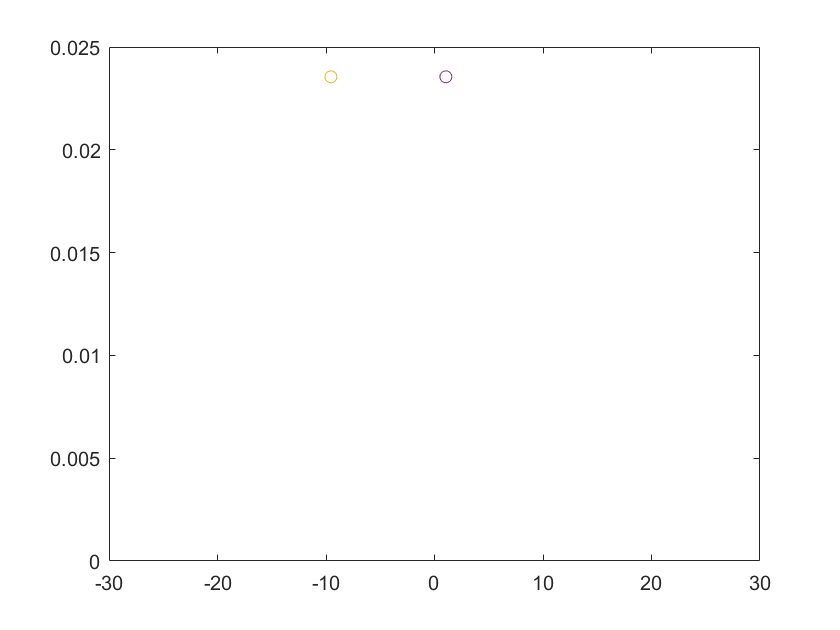

plot(x,f,'o-')

function y=minfun(x)
%描述目标函数
%~~~
    y = exp(x(1))*(4*x(1)^2+2*x(2)^2+4*x(1)*x(2)+2*x(2)+1);
end